clear variables;
close all;
clc;

Cargando imagen

I=imread("img\img1.tif");
I=I(:,:,1);

Definiendo los puntos

% points=[
%     0,0;
%     40,80;
%     100,100;
%     180,200;
%     255,255;
% ];

Aplicando Piecewise-Linear

% Iout=pieceWiseLinear(I,points);
% imshow([I,Iout]);

Ecualizando la imagen

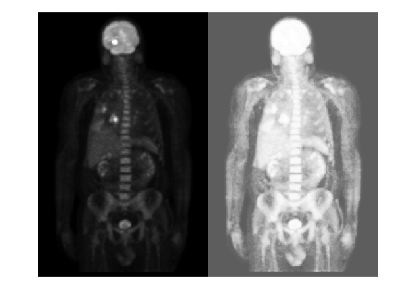

Iout=equalizer(I);
imshow([I,Iout]);

## Analisis en la frecuencia

Transformada de Fourier

[m,n]=size(I);
K=1/(m*n);
fft2(I);
Ifourier=K*fftshift(fft2(double(I)));%Se calcula la transformada de fourier
%Magnitud
Imagnitud=abs(Ifourier);
%Fase
Iangulo=angle(Ifourier);

Filtro notch optimo

Filtro de wiener